s = tf('s');
T = 0.005;
Ti = 1;
kp = 100;
Td = 1;
K = kp*(1 + 1/(Ti * s) + Td*s)

K =
 
  100 s^2 + 100 s + 100
  ---------------------
            s
 
Continuous-time transfer function.
Model Properties


G_Org = 1/(s*(s+1))

G_Org =
 
     1
  -------
  s^2 + s
 
Continuous-time transfer function.
Model Properties


G = (1/((T/2)*s+1))*(1/(s*(s+1)))

G =
 
              1
  --------------------------
  0.0025 s^3 + 1.002 s^2 + s
 
Continuous-time transfer function.
Model Properties


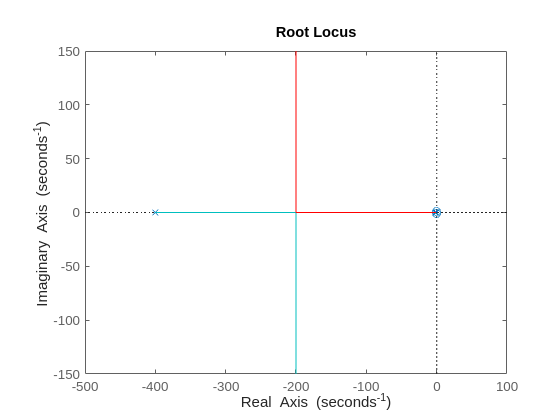

rlocus(K*G)

system = K*G/(1+K*G);
minreal(K*G_Org)

ans =
 
  100 s^2 + 100 s + 100
  ---------------------
        s^3 + s^2
 
Continuous-time transfer function.
Model Properties


c2d(K,T,'tustin')

ans =
 
  4.01e04 z^2 - 8e04 z + 3.99e04
  ------------------------------
             z^2 - 1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties
